# MATLAB code used in Kobayashi & Matsuo, *Cell Reports* (2023)

GitHub: [https://github.com/KyogoSKobayashi/Kobayashi_and_Matsuo_CellReports2023](https://github.com/KyogoSKobayashi/Kobayashi_and_Matsuo_CellReports2023)

Zenodo: [https://doi.org/10.5281/zenodo.7445183](https://doi.org/10.5281/zenodo.7445183)

- License

- Generate Demo Data

- Calcium Event Detetion

# License

## KyogoSKobayashi/Kobayashi_and_Matsuo_CellReports2023 is licensed under the MIT License

A short and simple permissive license with conditions only requiring preservation of copyright and license notices. Licensed works, modifications, and larger works may be distributed under different terms and without source code.

`MIT License`

`Copyright (c) 2022 KyogoSKobayashi`

`Permission is hereby granted, free of charge, to any person obtaining a copy`

`of this software and associated documentation files (the "Software"), to deal`

`in the Software without restriction, including without limitation the rights`

`to use, copy, modify, merge, publish, distribute, sublicense, and/or sell`

`copies of the Software, and to permit persons to whom the Software is`

`furnished to do so, subject to the following conditions:`

`The above copyright notice and this permission notice shall be included in all`

`copies or substantial portions of the Software.`

`THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR`

`IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY,`

`FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE`

`AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER`

`LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM,`

`OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN THE`

`SOFTWARE.`

# Generate DEMO data

- dFF0_data: 1600 frames-by-30 cells matrix of ΔF / F0 data .

- Session_labels: 4-by-1 string vector; "ContextA1","ContextA2","ContextB1", and "ContextB2".

- Frame_idx:  1600-by-1 string vector; "ContextA1","ContextA2","ContextB1", or "ContextB2".

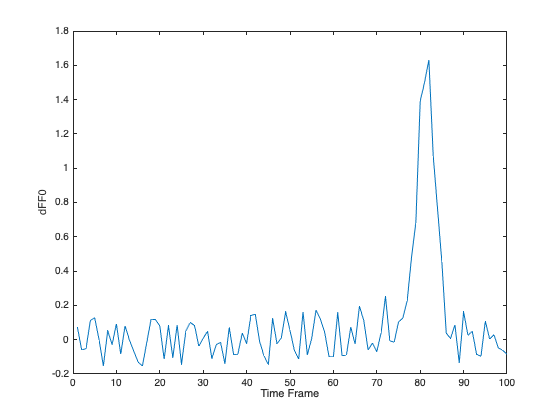

recording_Hz = 20; 

num_of_recording_frames_of_a_session = 400; % 20/400 = 20 sec
num_of_recording_cells = 30;

dFF0_data=zeros(num_of_recording_frames_of_a_session*4,num_of_recording_cells);
Session_labels = ["ContextA1";"ContextA2";"ContextB1";"ContextB2"];
Frame_idx = [repmat(Session_labels(1),num_of_recording_frames_of_a_session,1);...
             repmat(Session_labels(2),num_of_recording_frames_of_a_session,1);...
             repmat(Session_labels(3),num_of_recording_frames_of_a_session,1);...
             repmat(Session_labels(4),num_of_recording_frames_of_a_session,1)];


[~, y0] = titanium; %1-by-49 vector

rng default % for reproducibily
y1 = [y0,0.6]; %1-by-50 vector
y2 = y1-min(y1); %1-by-50 vector, represents a calcium event
one_event_trace = y2+(0.5-rand(size(y2)))/3; %1-by-50 vector with noise
no_event_trace = (0.5-rand(size(y2)))/3; %1-by-50 vector, bakcground fluctuation

figure; plot([no_event_trace,one_event_trace]);
ylabel ("dFF0");
xlabel("Time Frame");

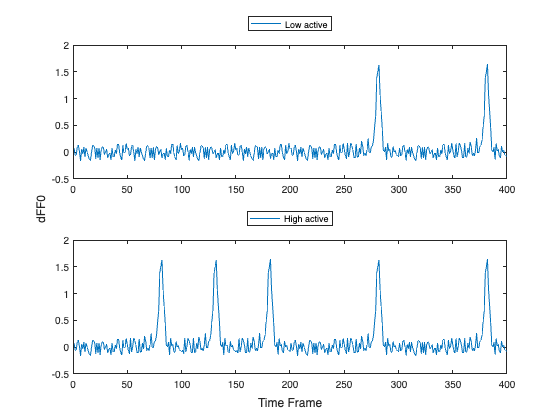


% high activity data
high_activity_data = [];
for ff = 1:(num_of_recording_frames_of_a_session/numel(y2))
    r = rand(1);
    if r > 0.3
        y = one_event_trace;
    else
        y = no_event_trace;
    end
    high_activity_data = [high_activity_data, y];
end

% low activity data
low_activity_data = [];
for ff = 1:(num_of_recording_frames_of_a_session/numel(y2))
    r = rand(1);
    if r > 0.8
        y = one_event_trace;
    else
        y = no_event_trace;
    end
    low_activity_data = [low_activity_data, y];
end

figure; t = tiledlayout("flow");
nexttile
plot(low_activity_data); legend("Low active",Location="northoutside")
nexttile
plot(high_activity_data); legend("High active",Location="northoutside")
ylabel (t, "dFF0");
xlabel(t, "Time Frame");

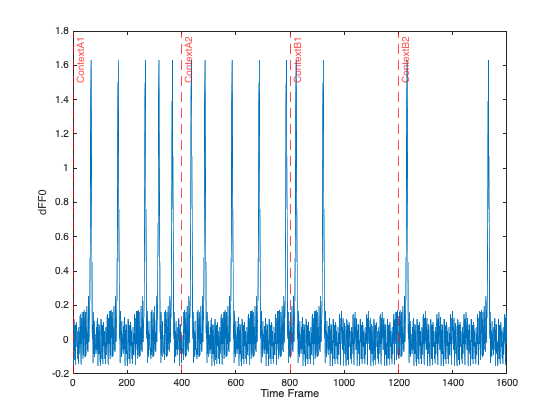


f = Frame_idx == "ContextA1";
d = high_activity_data;
for cc = 1:num_of_recording_cells
    r = randperm(num_of_recording_frames_of_a_session,1);
    dFF0_data(f,cc) = [d(r:end),d(1:r-1)];
end

f = Frame_idx == "ContextA2";
d = high_activity_data;
for cc = 1:num_of_recording_cells
    r = randperm(num_of_recording_frames_of_a_session,1);
    dFF0_data(f,cc) = [d(r:end),d(1:r-1)];
end

f = Frame_idx == "ContextB1";
d = low_activity_data;
for cc = 1:num_of_recording_cells
    r = randperm(num_of_recording_frames_of_a_session,1);
    dFF0_data(f,cc) = [d(r:end),d(1:r-1)];
end

f = Frame_idx == "ContextB2";
d = low_activity_data;
for cc = 1:num_of_recording_cells
    r = randperm(num_of_recording_frames_of_a_session,1);
    dFF0_data(f,cc) = [d(r:end),d(1:r-1)];
end

figure;
plot(dFF0_data(:,1));
xline(1,'--r',Session_labels(1));
xline(num_of_recording_frames_of_a_session+1,'--r',Session_labels(2));
xline(num_of_recording_frames_of_a_session*2+1,'--r',Session_labels(3));
xline(num_of_recording_frames_of_a_session*3+1,'--r',Session_labels(4));
ylabel ("dFF0");
xlabel("Time Frame");

# Calcium Event Detetion

-  Smoothed_dFF0_data: 1600 frames-by-30 cells matrix

-  Normalized_dFF0_data: 1600 frames-by-30 cells matrix

-  First_diff_dFF0_data: 1600 frames-by-30 cells matrix

-  Cal_Eve_Binary_data: 1600 frames-by-30 cells matrix

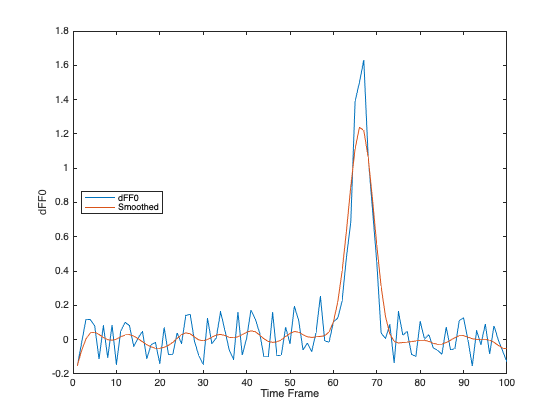

z_threshold = 2;

Smoothed_dFF0_data = dFF0_data*0;
[bFilt,aFilt] = butter(2,  2/(recording_Hz/2), 'low');
for ss = 1:numel(Session_labels)
    d1 = dFF0_data(Frame_idx == Session_labels(ss),:);
    smooted_d1 = filtfilt(bFilt,aFilt,d1); 
    Smoothed_dFF0_data(Frame_idx == Session_labels(ss),:) = smooted_d1;
end

figure;
plot (dFF0_data(1:100,1)); hold on
plot (Smoothed_dFF0_data(1:100,1)); legend(["dFF0","Smoothed"],Location="west");
ylabel ("dFF0");
xlabel("Time Frame");

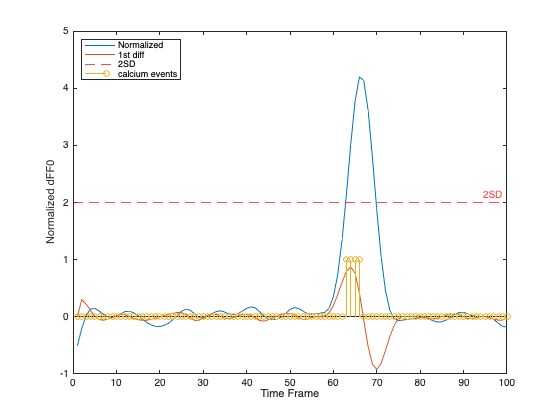


Normalized_dFF0_data = dFF0_data*0;
for ss = 1:numel(Session_labels)
    d1 = Smoothed_dFF0_data(Frame_idx == Session_labels(ss),:);
    d1_sd = std(d1,0,1);
    normalized_d1 = d1./d1_sd; 
    Normalized_dFF0_data(Frame_idx == Session_labels(ss),:) = normalized_d1;
end

First_diff_dFF0_data = dFF0_data*0;
for ss = 1:numel(Session_labels)
    d1 = Normalized_dFF0_data(Frame_idx == Session_labels(ss),:);
    d1_diff = diff(d1);
    zeros_d1_diff = [zeros(1,num_of_recording_cells);d1_diff];
    First_diff_dFF0_data(Frame_idx == Session_labels(ss),:) = zeros_d1_diff;
end

Cal_Eve_Binary_data = dFF0_data*0;
ones_data = ones(size(dFF0_data));
binary_threshold = Normalized_dFF0_data > z_threshold & First_diff_dFF0_data > 0;
Cal_Eve_Binary_data(binary_threshold) = ones_data(binary_threshold);


figure;
plot (Normalized_dFF0_data(1:100,1)); hold on
plot (First_diff_dFF0_data(1:100,1)); 
yline(z_threshold,'--r',"2SD");
stem(Cal_Eve_Binary_data(1:100,1));
legend(["Normalized","1st diff","2SD","calcium events"],Location="northwest");
ylabel ("Normalized dFF0");
xlabel("Time Frame");